# Pill detection algorithm

Omar & Javier Machine vision - Task 1

clear;
close all;

## Get images from webcam

%cam = webcam('HD Webcam C615');
%cam.Resolution = '640x480';
camHeight = 480;
camWidth = 640;

## Import images

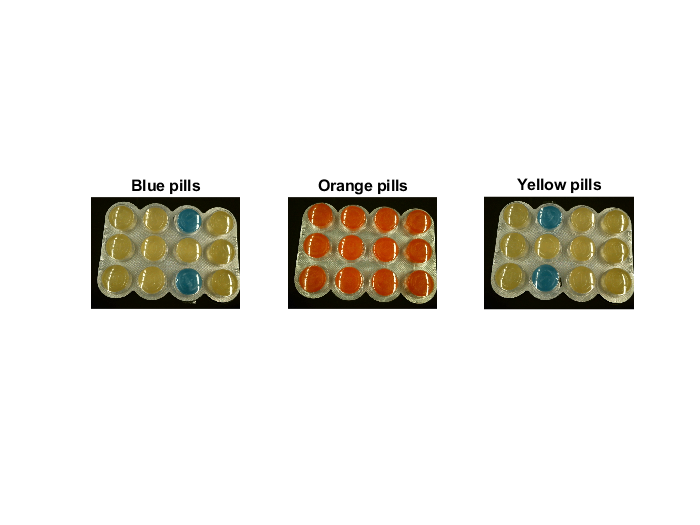

blueImg = imread("pill_pic_blueyellow3.png");
orangeImg = imread("pill_pic_orange2.png");
yellowImg = imread("pill_pic_blueyellow1.png");

figure
subplot(1,3,1);
imshow(blueImg)
title('Blue pills');

subplot(1,3,2);
imshow(orangeImg)
title('Orange pills');

subplot(1,3,3);
imshow(yellowImg)
title('Yellow pills');

% Blue color 
blue_high = [60; 125; 140];
blue_low = [20; 75; 80];

% Orange color 
orange_high = [190; 70; 10];
orange_low = [140; 40; 0];

% Yellow color  
yellow_high = [180; 165; 80];
yellow_low = [120; 100; 20];


% Select image to work with
img = blueImg;

## Extract pixels for each color

% Zeroes framework for the image
blue_pill = zeros(camHeight, camWidth, 1, 'uint8');
orange_pill = zeros(camHeight, camWidth, 1, 'uint8');
yellow_pill = zeros(camHeight, camWidth, 1, 'uint8');


% Gaussian blur
blue_pill_copy = blue_pill;
orange_pill_copy = orange_pill;
yellow_pill_copy = yellow_pill;

img = imgaussfilt(img, 2, 'FilterSize', [15,15]);

% Looping through every RGB channel and thresholding it
for m = 1: camHeight
    for n = 1: camWidth
        if(((img(m, n, 1) > blue_low(1)) && (img(m, n, 1) < blue_high(1)))...
                && ((img(m, n, 2) > blue_low(2)) && (img(m, n, 2) < blue_high(2)))...
                && ((img(m, n, 3) > blue_low(3)) && (img(m, n, 3) < blue_high(3))))
            blue_pill(m, n) = 255;
        end
        
        if(((img(m, n, 1) > orange_low(1)) && (img(m, n, 1) < orange_high(1)))...
                && ((img(m, n, 2) > orange_low(2)) && (img(m, n, 2) < orange_high(2)))...
                && ((img(m, n, 3) > orange_low(3)) && (img(m, n, 3) < orange_high(3))))
            orange_pill(m, n) = 255;
        end
        
        if(((img(m, n, 1) > yellow_low(1)) && (img(m, n, 1) < yellow_high(1)))...
                && ((img(m, n, 2) > yellow_low(2)) && (img(m, n, 2) < yellow_high(2)))...
                && ((img(m, n, 3) > yellow_low(3)) && (img(m, n, 3) < yellow_high(3))))
            yellow_pill(m, n) = 255;
        end
    end
end

## Pre-processing image erosion


% 4x4 mask for erosion
eroded_blue = imerode(blue_pill, strel('square',3)); %structuring element
eroded_orange = imerode(orange_pill, strel('square',3)); %structuring element
eroded_yellow = imerode(yellow_pill, strel('square',3)); %structuring element


denoise_blue = imnlmfilt(eroded_blue, 'ComparisonWindowSize',7);
denoise_orange = imnlmfilt(eroded_orange, 'ComparisonWindowSize',7);
denoise_yellow = imnlmfilt(eroded_yellow, 'ComparisonWindowSize',7);

## Display all images and ROI

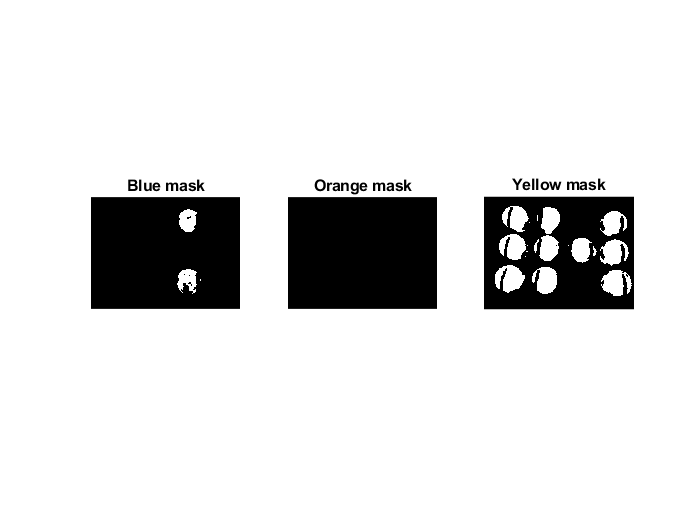

subplot(1,3,1);
imshow(denoise_blue)
title('Blue mask');

subplot(1,3,2);
imshow(denoise_orange)
title('Orange mask');

subplot(1,3,3);
imshow(denoise_yellow)
title('Yellow mask');

## Connected components + counting pills with a threshold of 2000 pixels

THRESHOLD = 2000; % is this optimal threshold?

blue_cc = bwconncomp(denoise_blue);
numpixels_blue = cellfun(@numel, blue_cc.PixelIdxList);
blues = find(numpixels_blue > THRESHOLD);
blue_pills = length(blues);
%[blue_largest, blue_id] = max(numpixels)

orange_cc = bwconncomp(denoise_orange);
numpixels_orange = cellfun(@numel, orange_cc.PixelIdxList);
oranges = find(numpixels_orange > THRESHOLD);
orange_pills = length(oranges);
%[orange_largest, orange_id] = max(numpixels);

yellow_cc = bwconncomp(denoise_yellow);
numpixels_yellow = cellfun(@numel, yellow_cc.PixelIdxList);
yellows = find(numpixels_yellow > THRESHOLD);
yellow_pills = length(yellows);
%[yellow_largest, yellow_id] = max(numpixels);

## Plot all the images with corresponding pill count

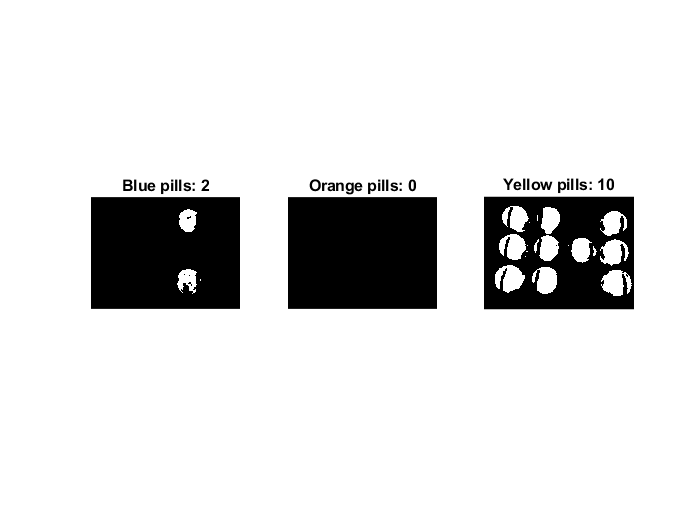

figure
subplot(1,3,1);
imshow(denoise_blue)
title(['Blue pills: ', int2str(blue_pills)]);

subplot(1,3,2);
imshow(denoise_orange)
title(['Orange pills: ', int2str(orange_pills)]);

subplot(1,3,3);
imshow(denoise_yellow)
title(['Yellow pills: ', int2str(yellow_pills)]);